clear all
close all
clc
load FlightData.mat
whos

  Name              Size                 Bytes  Class     Attributes

  Distance       1465x1465            17169800  double              
  Latitude       1465x1                  11720  double              
  Longitude      1465x1                  11720  double              
  Names          1465x1                 172870  cell                
  Traffic        1465x1465            17169800  double              



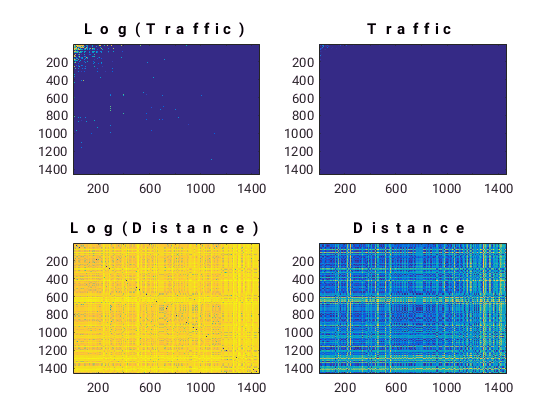

figure
subplot(2,2,1)
imagesc(log(Traffic));
title('Log(Traffic)');
subplot(2,2,2)
imagesc((Traffic));
title('Traffic');
subplot(2,2,3)
imagesc(log(Distance));
title('Log(Distance)');
subplot(2,2,4)
imagesc(Distance);
title('Distance');

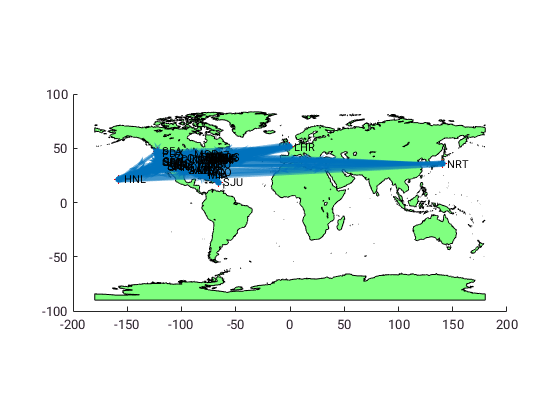

N = 50;
figure
geoshow('landareas.shp', 'FaceColor', [0.5 1.0 0.5]);
hold on
geoshow(Latitude(1:N),Longitude(1:N),'DisplayType','Point')
G = digraph( Traffic(1:N,1:N));
LWidths = G.Edges.Weight/mean(G.Edges.Weight);
plot(G,'XData',Longitude(1:N),'YData',Latitude(1:N),'ineWidth',LWidths,'NodeLabel',Names(1:N))